**Taller 2**

**Aggregation**

clc;
clear all;
rng(0);
datos = importdata("aggregation.txt");
X = datos(:,1:2);

% Diagrama de codo kmeans
fprintf("kmeans");

kmeans

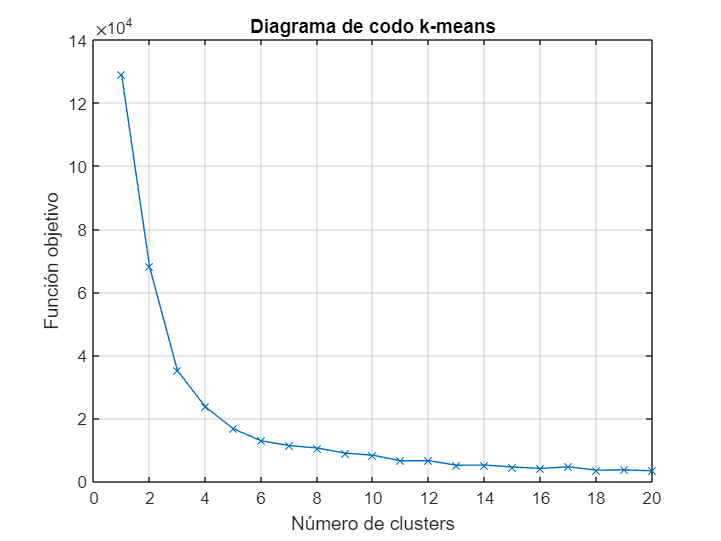

n = 20;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

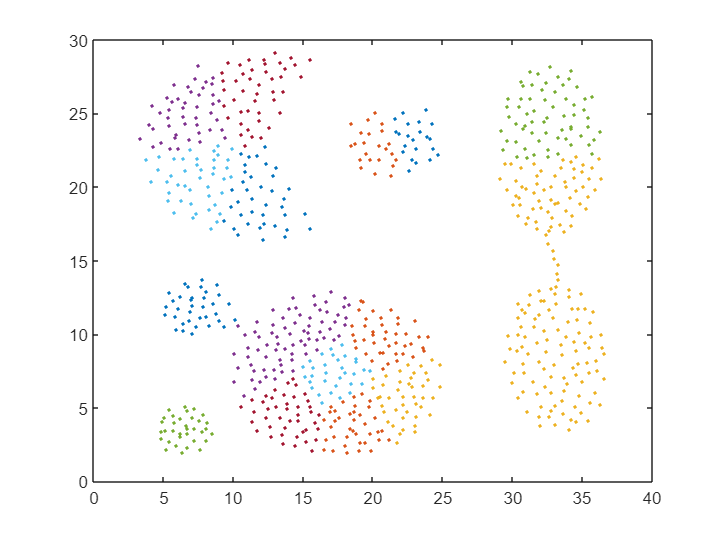


k=18;
idx = kmeans(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


fprintf("kmeans");

kmeans

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 2.0270

SSB = 12.0144

WB = 3.0368

SIL = 0.6038


fprintf("kmedoids");

kmedoids

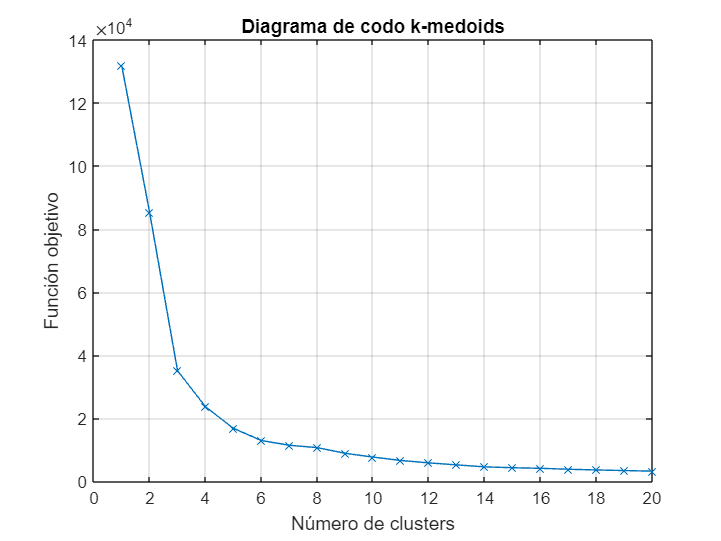


% Diagrama de codo kmedoids
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

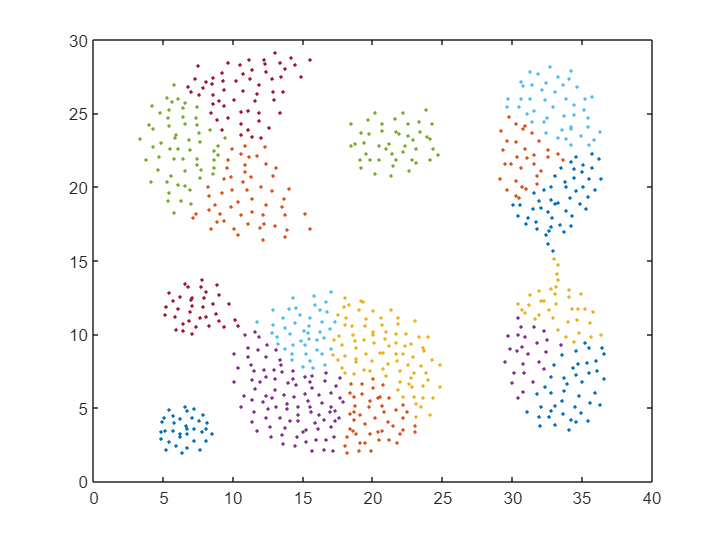


k=18;
idx = kmedoids(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 1.9570

SSB = 12.0232

WB = 2.9298

SIL = 0.5771


fprintf("DBSCAN");

DBSCAN


ep = clusterDBSCAN.estimateEpsilon(X,2,10)

ep = 1.1498

idx = dbscan(X,ep,10);
k1 = max(idx);
idx(idx==-1)= k1+1;
idx(idx==0)= k1+2;
k0 = min(idx)

k0 = 1

k1 = max(idx)

k1 = 11

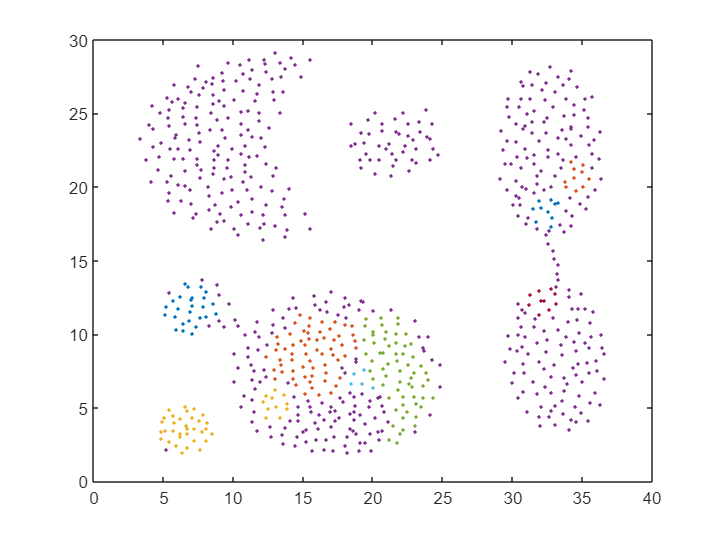


figure;
for i=k0:k1
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 8.7556

SSB = 6.0349

WB = 15.9592

SIL = -0.3618